# Final Project: CNN Portion

**Author:** Jack Bonney

**Student ID:** 4555214

**D Value:** 14

This live-script will walk through the processing involved with performing CNN on an image classification dataset. The dataset used is a collection of playing cards for all 53 types, the 13 base cards in each suit and the joker card. The data will be run through the google mobilenetv2 pretrained model. 

% Initialization
clc
clear
D = 14; % Personalization, will be used for RNG seeding
rng(D); % Set rng for reproducability

## Model Parameters

TrainingWeight = 0.9;
TotalTrials = 1;

Temp

% LOADING THE DATA 
data = imageDatastore("dataset\","IncludeSubfolders",true,"LabelSource",'foldernames');
[values, cardTypes] = grp2idx(data.Labels); % Gets number values for each card type, and where they are in the datastore
% SORTING THE DATA INTO TRAINING AND TESTING
X_train = zeros(224,224,3,round(TrainingWeight*length(values)));
X_test = zeros(224,224,3,round((1-TrainingWeight)*length(values)));
y_train = zeros(round(TrainingWeight*length(values)),1);
y_test = zeros(round((1-TrainingWeight)*length(values)),1);
% Spliting into individual label
temp = imread(cell2mat(data.Files(1)));
%
trainpointer = 1;
testpointer = 1;
for val = 1:max(values) % Loops over every possible card type
    indicies = find(values==val); % Gets all of the indicies for a give value
    shuffle = indicies(randperm(length(indicies)));
    % Loop over each image, store it in 
    for trainImg = 1:round(length(indicies)*TrainingWeight)
        X_train(:,:,:,trainpointer+trainImg-1) = readimage(data,shuffle(trainImg));
    end
    for testImg = 1:round(length(indicies)*(1-TrainingWeight))
        X_test(:,:,:,testpointer+testImg-1) = readimage(data,shuffle(testImg+round(length(indicies)*TrainingWeight)));
    end
    % Getting numerical lables
    y_train(trainpointer:trainpointer+round(length(indicies)*TrainingWeight)-1) = values(shuffle(1:round(TrainingWeight*length(indicies))));
    y_test(testpointer:testpointer+round(length(indicies)*(1-TrainingWeight))-1) = values(shuffle(round(TrainingWeight*length(indicies))+1:length(indicies)));
    % Updating Pointers
    trainpointer = trainpointer + round(length(indicies)*TrainingWeight);
    testpointer = testpointer + round(length(indicies)*(1-TrainingWeight));
end

### Showing success of train/test split

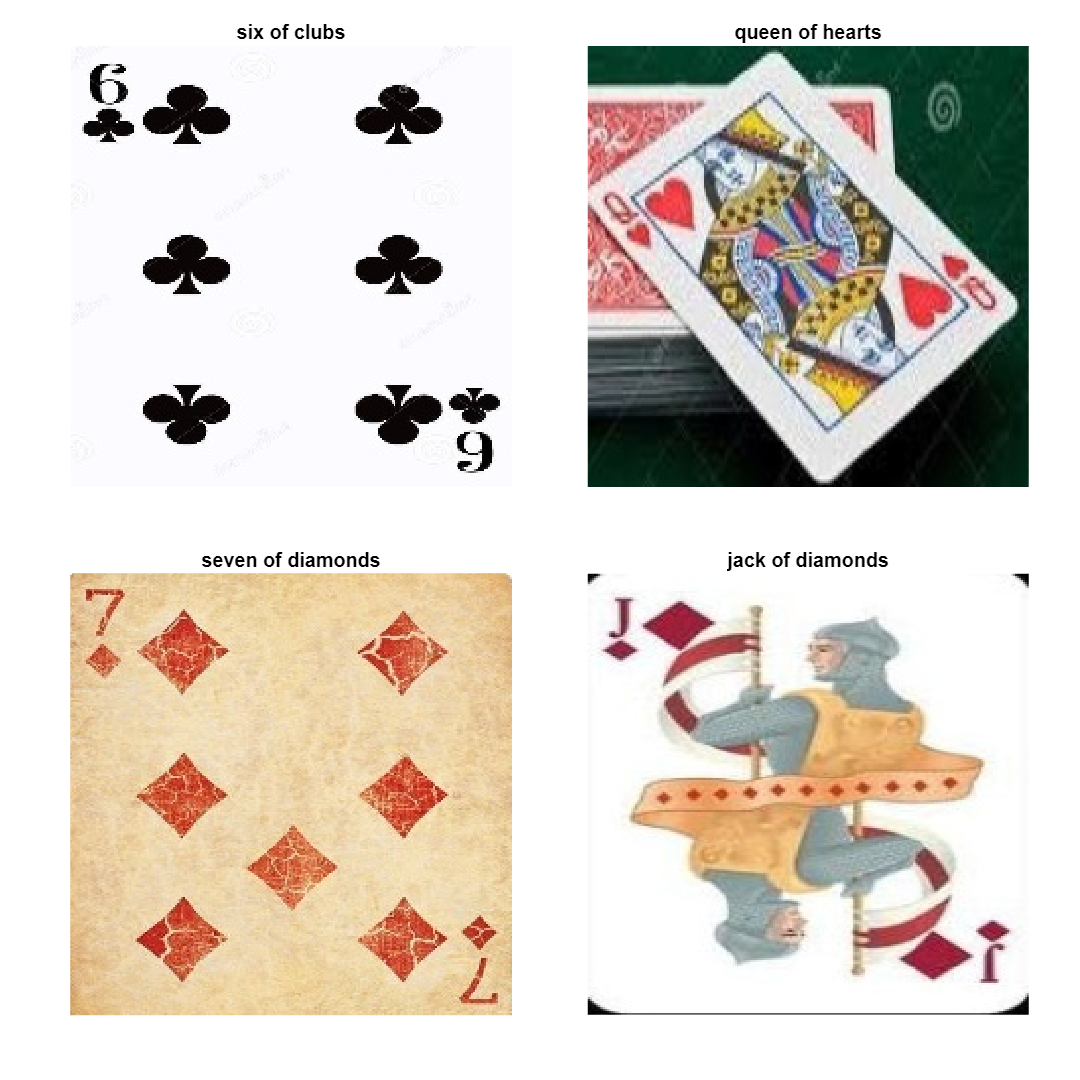

% Show traing images
testing = randperm(length(y_train),4);
datasetImagesTrain = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    imshow(uint8(X_train(:,:,:,testing(idx))))
    axis off;
    title(cardTypes(y_train(testing(idx))));
end
filename = sprintf('trainImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImagesTrain,outputFile,'Resolution',1200);

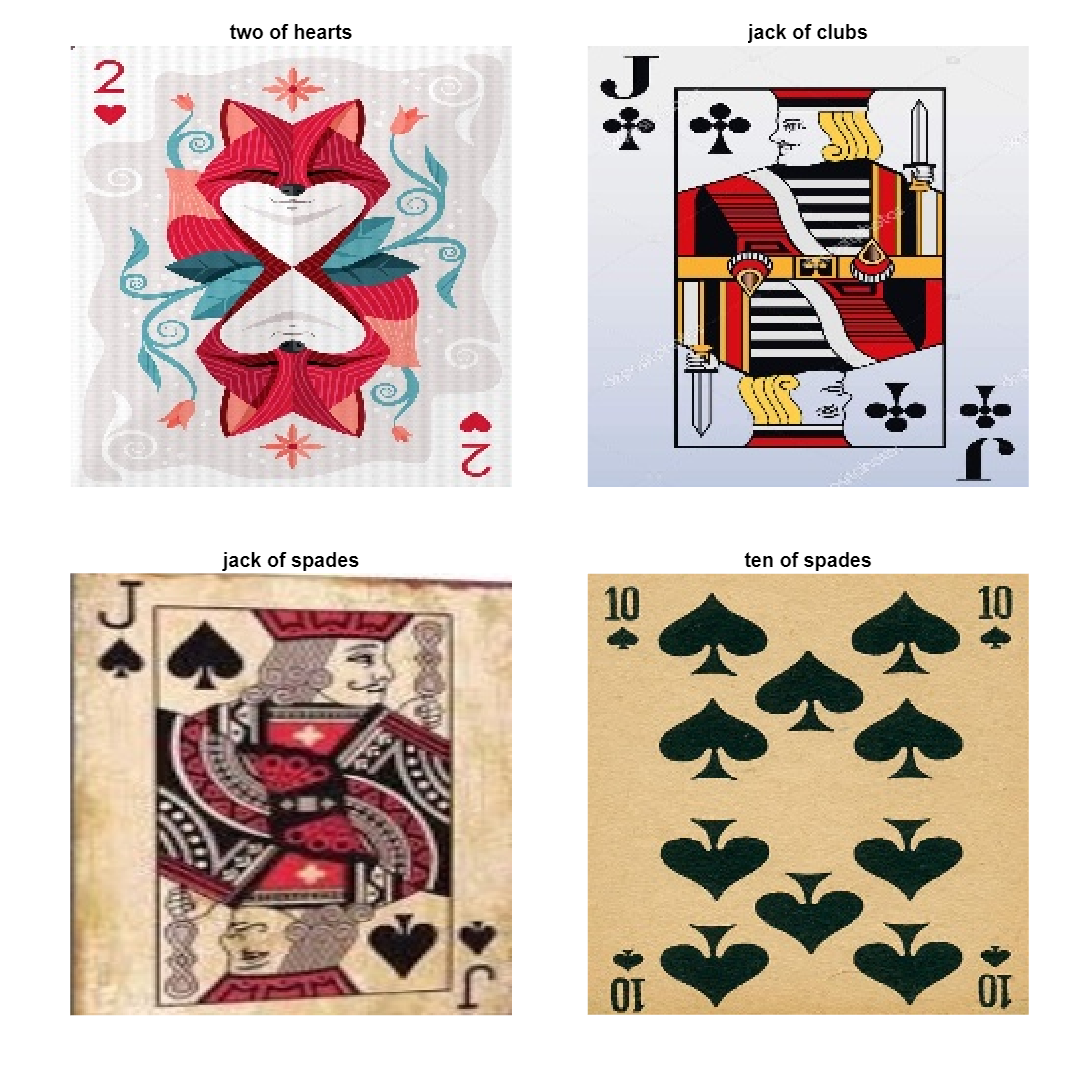

% Show traing images
testing = randperm(length(y_test),4);
datasetImageTest = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    imshow(uint8(X_test(:,:,:,testing(idx))))
    axis off;
    title(cardTypes(y_test(testing(idx))));
end
filename = sprintf('testImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImageTest,outputFile,'Resolution',1200);